x = sym('y')

$$x = y$$

solve(x.^2 == 1, x)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

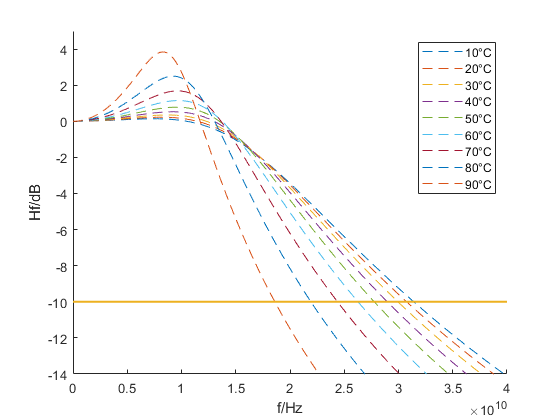


load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
% F = f(1101:end)*1e9;
f = 0:1e7:4e10;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [10, 20, 30, 40, 50, 60, 70, 80, 90] + 273.15;
figure
for i = 1:length(Ta)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--')
    [a, b] = min(abs(M+10));
    temp(i, 1) = Ta(i);
    temp(i, 2) = f(b);
end
y_1=[0, 4e10];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 4e10 -14 5])
legend('10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C');
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig18.png');

temp

temp = 	1.0e+10 *

    0.0000    3.1410
    0.0000    3.0750
    0.0000    2.9950
    0.0000    2.8970
    0.0000    2.7760
    0.0000    2.6270
    0.0000    2.4380
    0.0000    2.1930
    0.0000    1.8600


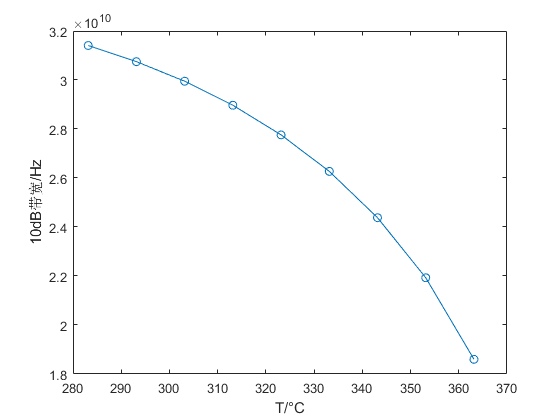

figure
plot(temp(:, 1), temp(:, 2), 'o-')
xlabel('T/°C')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig19.png');

temp = [];


temp =

     []



load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
f = 0:1e7:4.5e10;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [20] + 273.15;
eta = [0.1 0.2 0.3 0.4 0.5 0.6 1];
figure
for i = 1:length(eta)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta;
    x(1) = eta(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--')
    [a, b] = min(abs(M+10));
    temp(i, 1) = eta(i);
    temp(i, 2) = f(b);
end

ans = 0.1000

ans = 0.2000

ans = 0.3000

ans = 0.4000

ans = 0.5000

ans = 0.6000

ans = 1

y_1=[0, 4.5e10];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 4.5e10 -14 5])
legend('η=0.1', 'η=0.2', 'η=0.3', 'η=0.4', 'η=0.5', 'η=0.6', 'η=1');
temp

temp = 	1.0e+10 *

    0.0000    2.1010
    0.0000    2.8380
    0.0000    3.3010
    0.0000    3.6150
    0.0000    3.8340
    0.0000    3.9880
    0.0000    4.2640


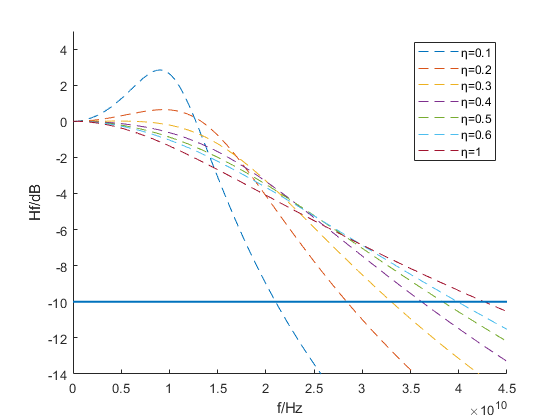

xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig20.png');

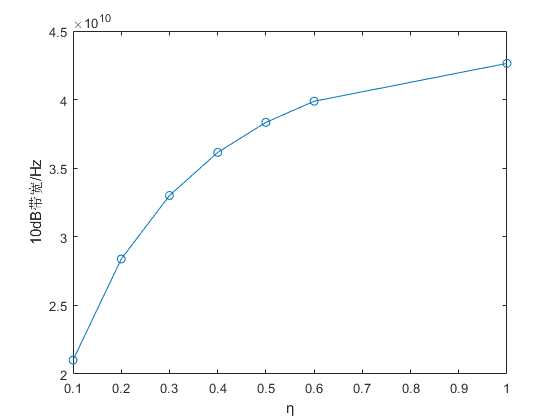

figure
plot(temp(:, 1), temp(:, 2), 'o-')
xlabel('η')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig21.png');